# Matched Filtering

## I- 1- Reasons for using Matched Filtering

You can see from the results in Receiver Operating Characteristics that the probability of detection increases with increasing SNR(Singal-to-Noise Ratio). For a deterministic signal in white Gaussian noise, you can maximize the SNR at the receiver by using a filter matched to the signal. The matched filter is a time-reversed and conjugated version of the signal. The matched filter is shifted to be causal.

## I- 2- Support for Matched Filtering

Use phased.MatchedFilter to implement a matched filter.

When you use phased.MatchedFilter, you can customize characteristics of the matched filter such as cofficients and window for spectrum weighting (we'll discuss its utility and how it works later). If you apply spectrum weighting, you can specify the coverage region and cofficient sample rate; Taylor, Kaiser and Chebychev window have additional properties you can specify.

## I- 3- Matched Filtering of Linear FM Waveform

This example compares the results of matched filtering with and without spectrum weighting. Spectrum weighting is often used with Linear FM waveforms to reduce sidelobes in the time domain.

Figure below depicted SideLobes, it seems like an absolute value (just positive values) of a sinus cardinal math function.

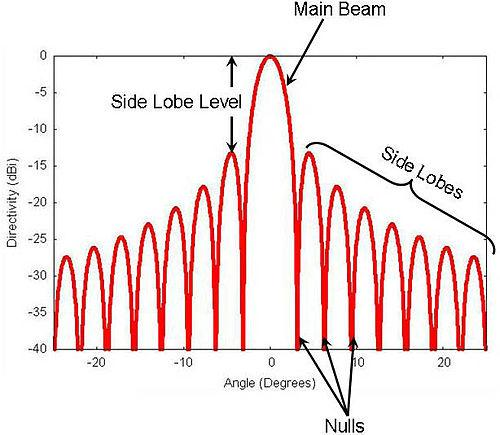

Now we create a linear FM waveform with a duration of 100 microseconds, a sweep bandwidth of 100 Khz, a sample rate of 1 Mhz and a pulse repetition frequency of 5 Khz. Add noise to the linear FM pulse and filter the noisy signal using a matched filter.This example applies a matched filter with and without spectrum weighting.

Specify the waveform :

waveform = phased.LinearFMWaveform('PulseWidth',1e-4,'PRF',5e3,...
    'SampleRate',1e6,'OutputFormat','Pulses','NumPulses',1,...
    'SweepBandwidth',1e5);
wav = getMatchedFilter(waveform);

Create a matched filter with no spectrum weighting, and a matched filter that uses a Taylor window for spectrum weighting.

filter = phased.MatchedFilter('Coefficients',wav);
taylorfilter = phased.MatchedFilter('Coefficients',wav,...
    'SpectrumWindow','Taylor');
hammingfilter = phased.MatchedFilter('Coefficients',wav,...
    'SpectrumWindow','Hamming');

Create the signal and add noise.

inputSignal = waveform();
rng(17)
noisySignal = inputSignal + 0.5*(randn(length(inputSignal),1) + 1j*randn(length(inputSignal),1));

Filter the noisy signal separately with each of the filters.

filtredSignal = filter(noisySignal);
filtredSignal_taylor = taylorfilter(noisySignal);
filtredSignal_hamming = hammingfilter(noisySignal);

Plot the real parts of the waveform and noisy signal.

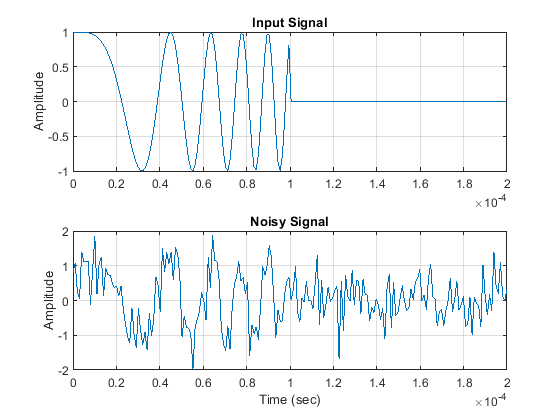

t = linspace(0,numel(inputSignal)/waveform.SampleRate,...    %% Time Vector
    waveform.SampleRate/waveform.PRF);              
subplot(2,1,1)                                       % Split the windowplot in 2 windows    
plot(t,real(inputSignal))
title('Input Signal')
xlim([0 max(t)])
grid on
ylabel('Amplitude')
subplot(2,1,2)
plot(t,real(noisySignal))
title('Noisy Signal')
xlim([0 max(t)])
grid on
xlabel('Time (sec)')
ylabel('Amplitude')

Plot the magnitudes of the two matched filter outputs.

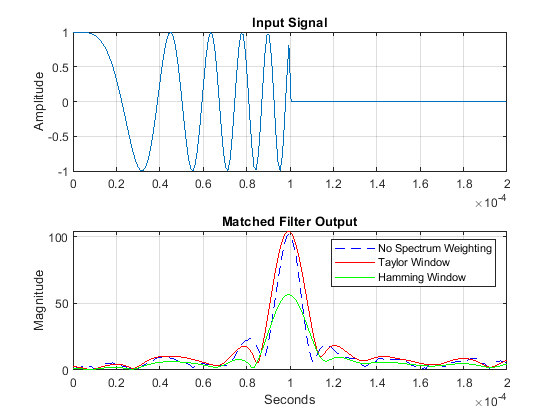

plot(t,abs(filtredSignal),'b--')
title('Matched Filter Output')
xlim([0 max(t)])
grid on
hold on
plot(t,abs(filtredSignal_taylor),'r-')
plot(t,abs(filtredSignal_hamming),'g-')
ylabel('Magnitude')
xlabel('Seconds')
legend('No Spectrum Weighting','Taylor Window','Hamming Window')
hold off

#### References : 

- [https://en.wikipedia.org/wiki/Matched_filter](https://en.wikipedia.org/wiki/Matched_filter)

- [https://www.mathworks.com/help/phased/ug/matched-filtering.html](https://www.mathworks.com/help/phased/ug/matched-filtering.html)